image_path = "Images\L97a.jpg"

image_path = "Images\W107b.jpg"

mask = K_Means(image_path)

img = 2048×2048×3 uint8 array
img(:,:,1) =

  Columns 1 through 1,666

   115   115   114   114   112   112   112   112   110   104    96    89    88    90    91    92    95   103   114   122   122   119   119   118   117   115   116   117   116   107    94    84    88    93    99   108   112   113   116   118   119   119   116   108   100    93    93    94   102   113   122   126   128   127   120   110   116   110   103   103   109   117   121   122   111   105   103   103   102   104   105   101    93    96   100   105   105   103   102   102    99    96    93    91    89    87    87    89    87    87    86    85    86    85    82    79    83    82    85   113   132   184   208   215   201   167   131   113   105    99    84    62    47    50    66    69    68    67    64    75    57    58    56    53    67    62    64    57    69    69    76    65    61    58    60    44    46    51    51    55    66    68    66    68    75    68    61    50    60    58    61    59    68    63    5

mask = 2048×2048 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

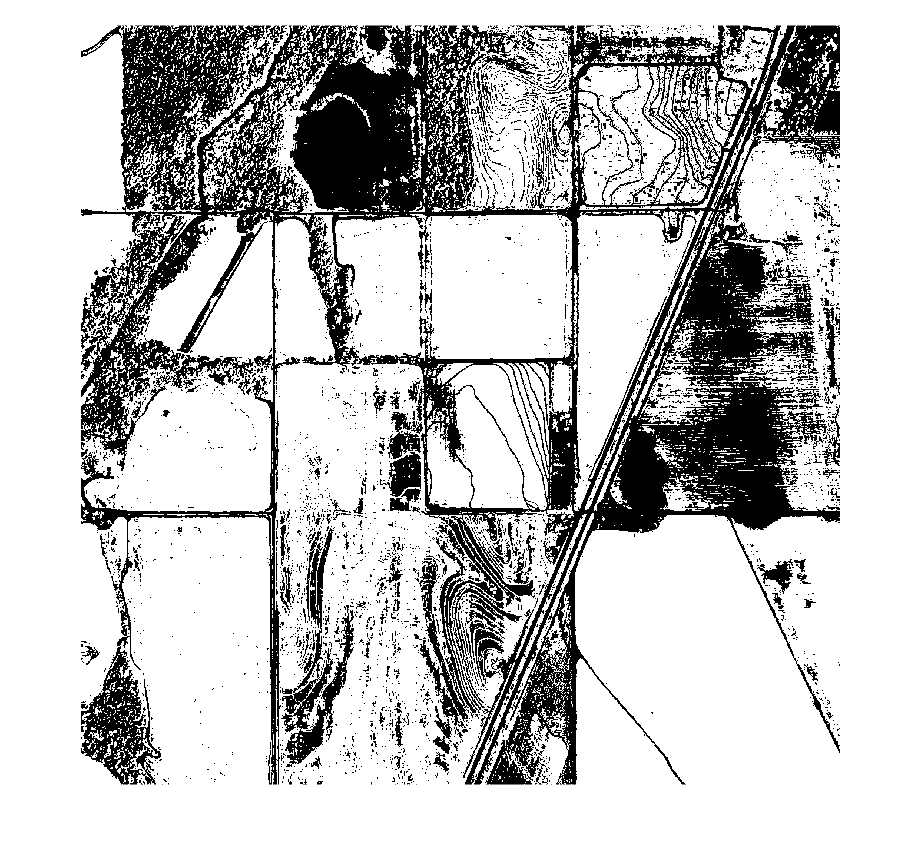

imshow(mask)

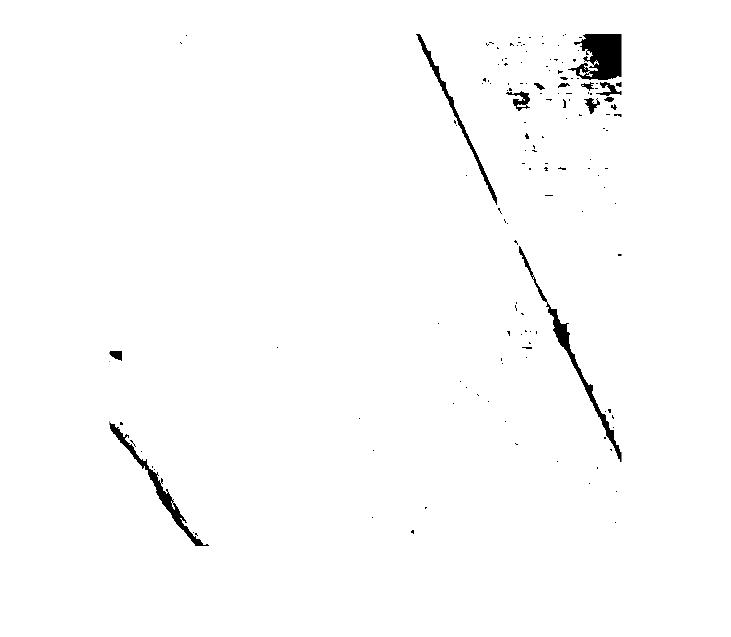

accuracy_ls =     0.5074    0.7385    0.9065    0.8877    0.4948    0.8687    0.7651    0.7361    0.7299    0.9501    0.8360    0.7630    0.7700    0.6150    0.7434    0.9738


precession_ls =     0.4841    0.7364    0.9419    0.8922    0.2500    0.8830    0.7899    0.7417    0.7328    0.9821    0.8354    0.8557    0.8260    0.5707    0.7071    0.9849


total_confusion_matrix =       614119      231683
      741949     2606553


%imwrite(mask,"Output_L97a.jpg")
[accuracy_ls,precession_ls,total_confusion_matrix]=Evaluation(image_path,mask)

mean_accuracy = mean(accuracy_ls)

mean_accuracy = 0.7679

mean_precession = mean(precession_ls)

mean_precession = 0.7634

accuracy=(total_confusion_matrix(1,1)+total_confusion_matrix(2,2))/(total_confusion_matrix(1,1)+total_confusion_matrix(1,2)+total_confusion_matrix(2,1)+total_confusion_matrix(2,2));
accuracy

accuracy = 0.7679

precession = (total_confusion_matrix(2,2))/(total_confusion_matrix(2,1)+total_confusion_matrix(2,2));
precession

precession = 0.7784

function [accuracy_ls,precession_ls,tcm]=Evaluation(image_path,mask)
    image_file = split(image_path,"\");
    image_name = split(image_file(2),".");
    image_name = image_name(1);
    accuracy_ls = [];
    precession_ls = [];
    img = imread(image_path);
    tcm=[[0 0];[0 0]];
    position = [[0 0 512 512];[0 512 512 511];[0 1024 512 511];[0 1536 512 511];[512 0 511 512];[512 512 511 511];[512 1024 511 511];[512 1536 511 511];[1024 0 511 512];[1024 512 511 511];[1024 1024 511 511];[1024 1536 511 511];[1536 0 511 512];[1536 512 511 511];[1536 1024 511 511];[1536 1536 511 511]];
    for i = 1:16
        crop_im = imcrop(img,position(i,:));
        crop_mask = imcrop(mask,position(i,:)); 
        [BW,maskedRGBImage] = GetMask(i,image_name,crop_im);
        imshow(crop_mask)
        imshow(BW)
        C = segmentationConfusionMatrix(crop_mask, BW);
        tcm(1,1) = tcm(1,1)+C(1,1);
        tcm(1,2) = tcm(1,2)+C(1,2);
        tcm(2,1) = tcm(2,1)+C(2,1);
        tcm(2,2) = tcm(2,2)+C(2,2);
        accurac = (C(1,1)+C(2,2))/(C(1,1)+C(1,2)+C(2,1)+C(2,2));
        precesion = (C(2,2))/(C(2,1)+C(2,2));
        accuracy_ls(i)=accurac;
        precession_ls(i) = precesion;
    end
end

function [BW,maskedRGBImage] = GetMask(idx,image_name,RGB)
    path = strcat("Evaluation\",image_name,"\Functions");
    addpath(genpath(path))
    switch idx
        case 1
            [BW,maskedRGBImage] = segmentImage_mask_01(RGB);
        case 2
            [BW,maskedRGBImage] = segmentImage_mask_02(RGB);
        case 3
            [BW,maskedRGBImage] = segmentImage_mask_03(RGB);
        case 4
            [BW,maskedRGBImage] = segmentImage_mask_04(RGB);
        case 5
            [BW,maskedRGBImage] = segmentImage_mask_11(RGB);
        case 6
            [BW,maskedRGBImage] = segmentImage_mask_12(RGB);
        case 7
            [BW,maskedRGBImage] = segmentImage_mask_13(RGB);
        case 8
            [BW,maskedRGBImage] = segmentImage_mask_14(RGB);
        case 9
            [BW,maskedRGBImage] = segmentImage_mask_21(RGB);
        case 10
            [BW,maskedRGBImage] = segmentImage_mask_22(RGB);
        case 11
            [BW,maskedRGBImage] = segmentImage_mask_23(RGB);
        case 12
            [BW,maskedRGBImage] = segmentImage_mask_24(RGB);
        case 13
            [BW,maskedRGBImage] = segmentImage_mask_31(RGB);
        case 14
            [BW,maskedRGBImage] = segmentImage_mask_32(RGB);
        case 15
            [BW,maskedRGBImage] = segmentImage_mask_33(RGB);
        case 16
            [BW,maskedRGBImage] = segmentImage_mask_34(RGB);
    end
end


function mask = K_Means(image_path)
    img = imread(image_path)
    numColors=2;
    lab_he = rgb2lab(img);
    ab = lab_he(:,:,2:2);
    ab = im2single(ab);
    pixel_labels = imsegkmeans(ab,numColors,NumAttempts=2);
    mask1 = pixel_labels == 2;
    mask2 = pixel_labels ~= 1;
    mask = mask1 | mask2;
    
    numberOfZeros = numel(mask) - nnz(mask);
    if numberOfZeros>nnz(mask)
        mask = ~mask;
    end
               
end
